## Back to basics: Step 2.

## State model

This is our input:


$$s_{t+1} =s_t +v_t \cdot h+w_t$$


This is the output:


$$y=||r-r^{\left(i\right)} ||_2 \;+v_t$$


But if the input is expressed in terms of arc position (how far around the circle is the vehicle), then the velocity is how quickly the vehicle travels along the arc, this is tangential velocity.

To determine this, we need to transform back from curvilinear co-ordinates, back to cartesian.The original function provided in the notes refers to the y output co-ordinate points as $r$.

Original: $r=\left\lbrack x,y\right\rbrack$

New: $y=||\;\left\lbrack \begin{array}{cc}
R\cdot \cos \left(\frac{s_t }{R}\right) & R\cdot \sin \left(\frac{s_t }{R}\right)
\end{array}\right\rbrack -r^{\left(i\right)} \;||_2 \;+v_t$

If the co-ordinates were kept as cartesian:

$s=\left\lbrack R\cdot \textrm{acos}\left(\frac{x}{R}\right),R\cdot \textrm{asin}\left(\frac{x}{R}\right)\right\rbrack$, also note here that this is just $s$. Velocity also becomes more complicated as it must be decomposed into $x$ and $y$ terms.

The full system in the new arc position co-ordinates leads to the following system:


$$s=\left\lbrack \begin{array}{c}
s\\
v_s 
\end{array}\right\rbrack$$
    
$$A=\left\lbrack \begin{array}{cc}
1 & h\\
0 & 1
\end{array}\right\rbrack$$



$$s_{t+1} ={\textrm{As}}_t +w_t$$



$$y_t =h\left(x_t ,v_t \right)$$


This should allow mapping between circular and cartesian co-ordinates. So doing it this way keeps the dynamics linear. If you keep it in Cartesian co-ordinates, the dynamics of the system also becomes non-linear, so you calculate the Jacobian for both systems.

Note: To increase the number of states and get lateral movement in these co-ordinates, this should corresponsd to a circle of varying radius. So instead of track radius staying constant in the above equations, it will become a variable in the Jacobian calculation.

Note 2: The equations are correct by convention, but to ensure the vehicle travels in a clockwise direction, we can shift the sign of the sin term to ensure a positive velocity corresponds to clockwise velocity.

% Make sure to add Casadi to path and import it.
import casadi.*

% Setup.
fs = 100;
ht = 1/fs;

% State transition matrix.
A = [1 0 ht 0;
     0 1 0 ht;
     0 0 1 0;
     0 0 0 1];

% Noise variance for velocity, no position variance.
v_std = 0.1;
Q = [v_std^2 0;
    0 v_std^2];

G = [0 ht;
     1 0;
     0 10*ht;
     1 0];

% Define where the beacons are on the track. These are triangular around
% the track. If we change the locations, this will provide worse estimates.
beaconLocations = [-45 0 45; -45 45 -45]';
nBeacons = length(beaconLocations);

% Track size.
trackRadius = 40;

% Jacobian set up.
% Variable.
x = MX.sym('x', 4);

% Arc positiion.
s = x(1);
sy = x(2);

% Map arc-length position to cartesian co-ordinates.
px = sy * cos(s / sy);
py = sy * -sin(s / sy);

% Range to each beacon, loop over the function for each beacon.
h = MX.zeros(nBeacons, 1);
for i = 1 : nBeacons
    h(i) = sqrt((px - beaconLocations(i, 1)) ^ 2 + (py - beaconLocations(i, 2)) ^ 2);
end

% Jacobian here.
jh = jacobian(h, x);
Jhx = Function('h', {x}, {h});
Jh = Function('Jh', {x}, {jh});

% Measurement noise.
mu = zeros(1, nBeacons);
r = 1.5;
R = r^2 * eye(nBeacons);

% Initialisation.
nSamples = 800;
timeVector = (0 : nSamples) * ht;
stateVector = zeros(4, nSamples + 1);

% Need x and y co-ordinates.
measurementVector = zeros(nBeacons, nSamples);
currentPositionTrackX = zeros(1, nSamples);
currentPositionTrackY = zeros(1, nSamples);

% Kalman Filter estimates initialisiation.
x_mu = zeros(4, nSamples);
sigma_mu = cell(1, nSamples);

% State initialisation. If you want a mean value for velocity, just set the
% initial state to that value.
stateVector(:, 1) = [0 20 15 0.2]';

% Initial estimate. Offset needs to be small for convergence.
x_tu = [5; 20; 15; 1];
sigma_tu = diag([10, 5, 2, 1]);

for t = 1 : nSamples

    %% ----------------- STATE DYNAMICS SECTION --------------------
    % Noise for the velocity.
    processNoise = mvnrnd([0 0], Q)';

    % Note that there's no input terms here. They're in the script for
    % testing, but omitted because the model doesn't call for it.
    stateVector(:, t + 1) = A * stateVector(:, t) + G * processNoise;

    currentPositionTrackX(:, t) = stateVector(3, t) * cos(stateVector(1, t) / stateVector(3, t));
    currentPositionTrackY(:, t) = -stateVector(3, t) * sin(stateVector(1, t) / stateVector(3, t));
    trackPosition = [currentPositionTrackX(:, t) currentPositionTrackY(:, t)];

    % Euclidean distance of the current position to each beacon location.
    distFromBeacons = vecnorm(trackPosition - beaconLocations, 2, 2);

    % Actual noise model provided.
    measurementNoise = mvnrnd(mu, R)';

    % Final measurement.
    measurementVector(:, t) =  distFromBeacons + measurementNoise;

    %% -------------- KALMAN FILTER SECTION ------------------------
    % Jacobian steps to compute before Kalman Filter.
    h_x = full(Jhx(x_tu));
    C_lin = full(Jh(x_tu));
 
    % Keep a log of sigma and the estimated state. Measurement update.
    [sigma_mu{:, t}, x_mu(:, t)] = measurementUpdate(sigma_tu, x_tu, ...
        measurementVector(:, t), C_lin, R, h_x);

    % Time update step.
    [sigma_tu, x_tu] = timeUpdate(sigma_mu{:, t}, x_mu(:, t), A, Q, G);

end

% Set this up for later.
positionError = x_mu(1,:) - stateVector(1,1 : end - 1);
velocityError = x_mu(3,:) - stateVector(3,1 : end - 1);

## Plotting section

Learned some cool plotting techniques for animating the graphs. I'm pretty sure you can just remove the pause and it should be almost instant and bypass the animation for playing about with.

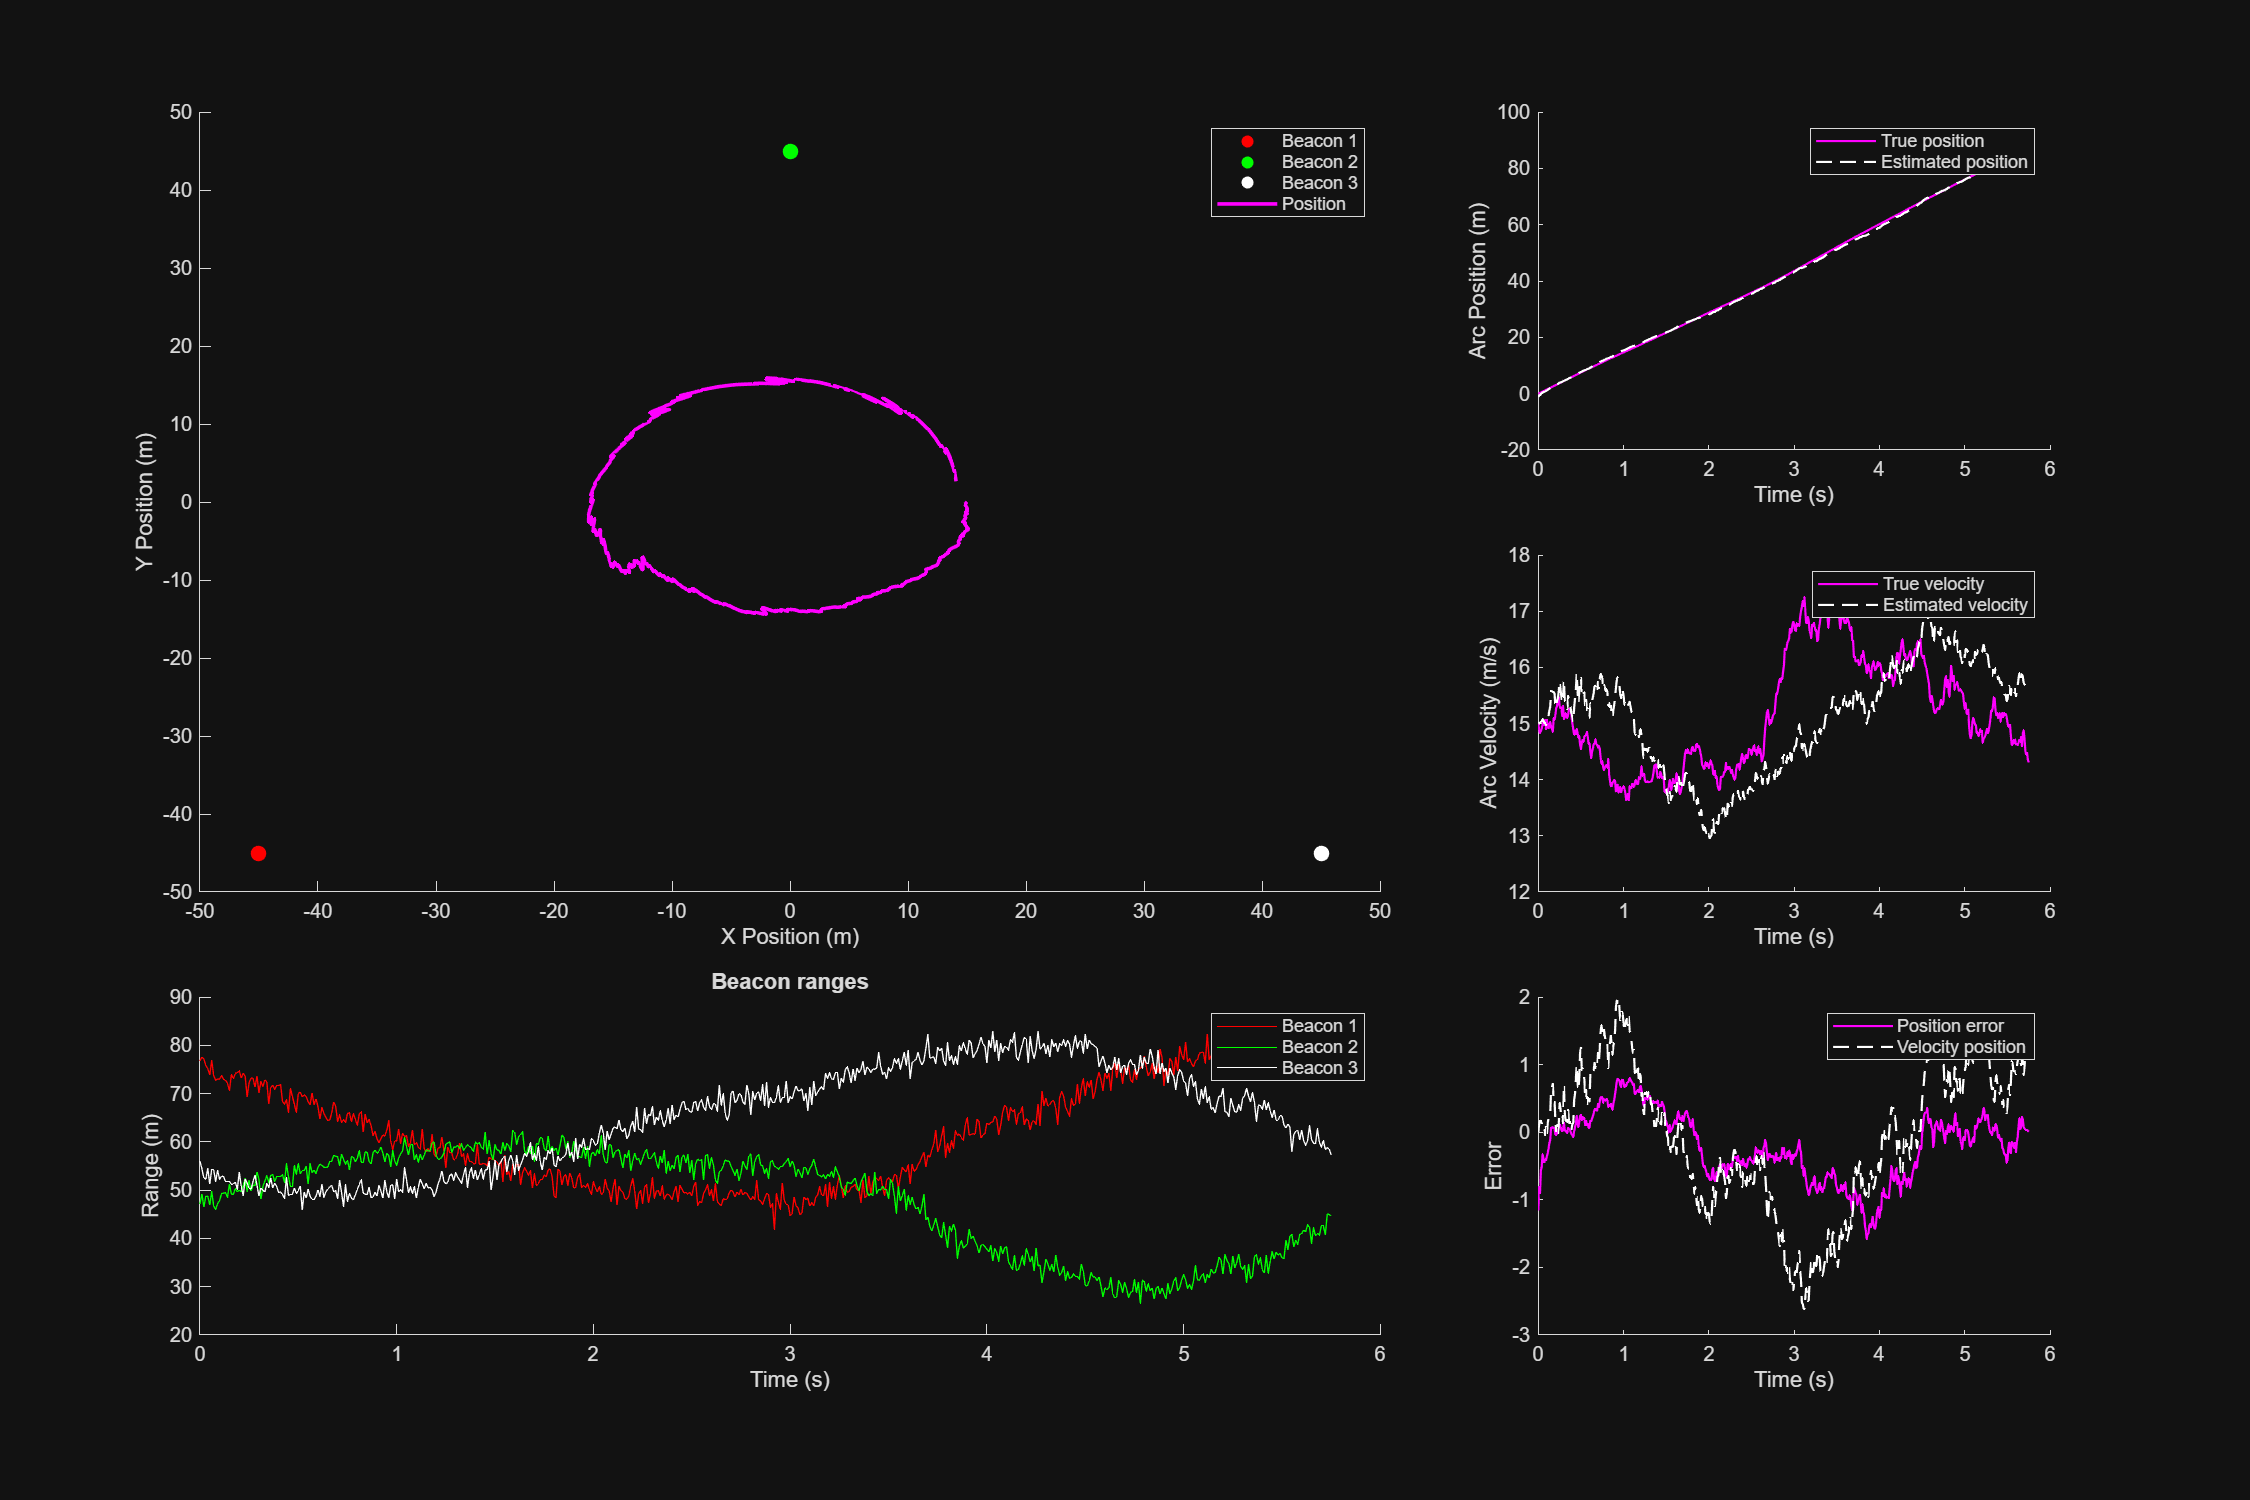

f = figure;
f.Position = [0 0 1500 1000];
tiledlayout(3, 3)

t1 = nexttile([2, 2]);
t2 = nexttile([1, 2]);
t3 = nexttile;
t4 = nexttile;
t5 = nexttile;

hold(t1, 'on')
hold(t2, 'on')
hold(t3, 'on')
hold(t4, 'on')
hold(t5, 'on')

beaconColours = {[1 0 0], [0 1 0], [1 1 1]};

xlabel(t1, 'X Position (m)')
ylabel(t1, 'Y Position (m)')

xlabel(t2, 'Time (s)')
ylabel(t2, 'Range (m)')
title(t2, 'Beacon ranges')

ylabel(t3, 'Arc Position (m)');
xlabel(t3, 'Time (s)')

ylabel(t4, 'Arc Velocity (m/s)')
xlabel(t4, 'Time (s)')

ylabel(t5, 'Error')
xlabel(t5, 'Time (s)')

%% --- Plot static elements (only once) ---

% Beacons
for i = 1:nBeacons
    scatter(t1, beaconLocations(i,1), beaconLocations(i,2), ...
        60, beaconColours{i}, 'filled', ...
        'DisplayName', "Beacon " + string(i));
end

%% --- Pre-create animated objects ---

% Trajectory
h_traj = plot(t1, NaN, NaN, 'm', 'LineWidth', 1.8, ...
    'DisplayName', 'Position');

% Tile 3
sTrajectory = plot(t3, NaN, NaN, 'm', 'LineWidth', 1.1, ...
    'DisplayName', 'True position');
sEstTrajectory = plot(t3, NaN, NaN, 'w--', 'LineWidth', 1.1, ...
    'DisplayName', 'Estimated position');

% Tile 4
vTrajectory = plot(t4, NaN, NaN, 'm', 'LineWidth', 1.1, ...
    'DisplayName', 'True velocity');
vEstTrajectory = plot(t4, NaN, NaN, 'w--', 'LineWidth', 1.1, ...
    'DisplayName', 'Estimated velocity');

% Tile 5
errorSTrajectory = plot(t5, NaN, NaN, 'm', 'LineWidth', 1.1, ...
    'DisplayName', 'Position error');
errorVTrajectory = plot(t5, NaN, NaN, 'w--', 'LineWidth', 1.1, ...
    'DisplayName', 'Velocity position');

% Beacon range lines
h_range = gobjects(1, nBeacons);

for i = 1:nBeacons
    h_range(i) = plot(t2, NaN, NaN, ...
        'Color', beaconColours{i}, ...
        'DisplayName', "Beacon " + string(i));
end

legend(t1, 'show')
legend(t2, 'show')
legend(t3, 'show')
legend(t4, 'show')
legend(t5, 'show')

%% --- Animation loop ---

for i = 1:nSamples
    
    % Update trajectory
    set(h_traj, ...
        'XData', currentPositionTrackX(1:i), ...
        'YData', currentPositionTrackY(1:i));
    
    % Update beacon ranges
    for b = 1:nBeacons
        set(h_range(b), ...
            'XData', timeVector(1:i), ...
            'YData', measurementVector(b,1:i));
    end

    set(sTrajectory, ...
        'XData', timeVector(1:i), ...
        'YData', stateVector(1, 1:i));
    set(sEstTrajectory, ...
        'XData', timeVector(1:i), ...
        'YData', x_mu(1, 1:i));

    set(vTrajectory, ...
        'XData', timeVector(1:i), ...
        'YData', stateVector(3, 1:i));
    set(vEstTrajectory, ...
        'XData', timeVector(1:i), ...
        'YData', x_mu(3, 1:i));

    set(errorSTrajectory, ...
        'XData', timeVector(1:i), ...
        'YData', positionError(1, 1:i));
    set(errorVTrajectory, ...
        'XData', timeVector(1:i), ...
        'YData', velocityError(1, 1:i));
        
    drawnow limitrate
    pause(0.01)
end

function [sigma, x] = measurementUpdate(sigma, x, y, C, R, h_x)
    z = C * sigma * C' + R;
    x = x + sigma * C' * linsolve(z, y - h_x);
    sigma = sigma - sigma * C' * linsolve(z, C * sigma);
end

function [sigma, x] = timeUpdate(sigma, x, A, Q, G)
    x = A * x;
    sigma = A * sigma * A' + G * Q *G';
end
